folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Optimal_control_theory\lab3\tex\images\";

A = [0 1; -2 9];
B = [4; 8];
Q = [3 0; 0 2];
r = 1;

[P, e, w] = care(A, B, Q, r);
P

P =     2.6761   -1.7319
   -1.7319    1.4969


K = B.'*P

K =    -3.1508    5.0479


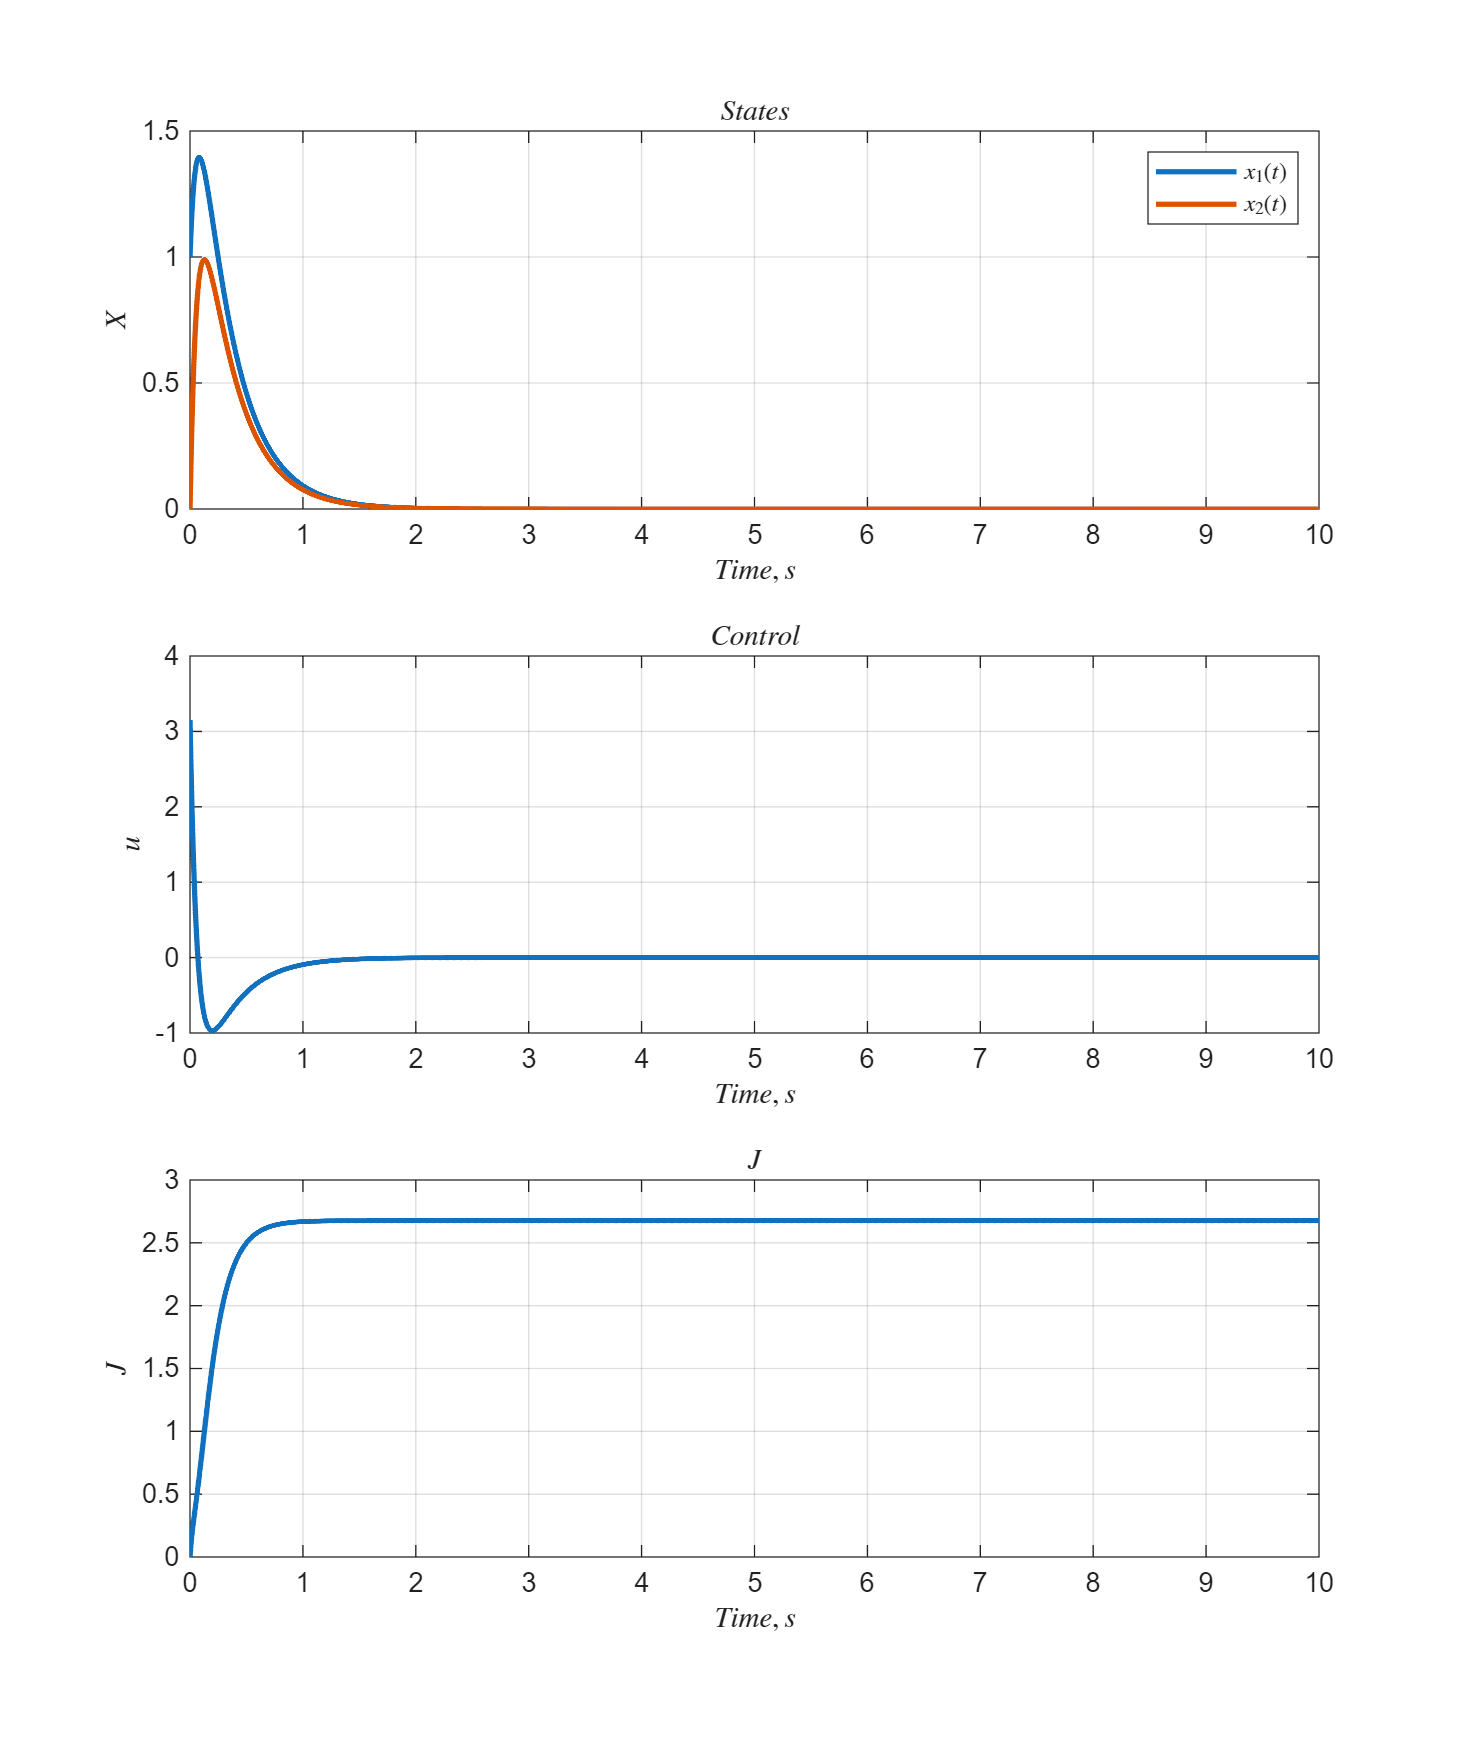

out = sim("lab3.slx", 5);

fig = figure;
fig.Position = [100 100 1000 1200];

subplot(3,1,1);
plot(out.X.Time, out.X.Data, LineWidth=2);
title("$States$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$X$", Interpreter="latex");
grid("on");
legend({"$x_1(t)$", "$x_2(t)$"}, Interpreter="latex");

subplot(3,1,2);
plot(out.u.Time, out.u.Data, LineWidth=2);
title("$Control$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$u$", Interpreter="latex");
grid("on");

subplot(3,1,3);
plot(out.J.Time, out.J.Data, LineWidth=2);
title("$J$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$J$", Interpreter="latex");
grid("on");
exportgraphics(fig, fullfile(folder, "task2.png"), Resolution=600);

out = sim("lab3.slx", 10);

fig = figure;
fig.Position = [100 100 1000 1200];

subplot(3,1,1);
plot(out.X.Time, out.X.Data, LineWidth=2);
title("$States$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$X$", Interpreter="latex");
grid("on");
legend({"$x_1(t)$", "$x_2(t)$"}, Interpreter="latex");

subplot(3,1,2);
plot(out.u.Time, out.u.Data, LineWidth=2);
title("$Control$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$u$", Interpreter="latex");
grid("on");

subplot(3,1,3);
plot(out.J.Time, out.J.Data, LineWidth=2);
title("$J$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$J$", Interpreter="latex");
grid("on");
exportgraphics(fig, fullfile(folder, "task2.png"), Resolution=600);